# **Deploy an Inference Model to an NVIDIA Jetson Nano(4.3)**

**前言：**

**此範例是Deployment and Classification of Webcam Images on NVIDIA Jetson TX2 Platform的更新版**

**上述範例中使用的是舊版的JetPack與OpenCV**

**此範例中使用的是4.3版的JetPack與4.1.1版OpenCV**

**範例內的部分圖文是使用ADD-ON上的Deep Learning For Object Detection教學範例做修改**

**Preface:**

**This example is an updated version of the deployment and classification of webcam images on the NVIDIA Jetson TX2 platform**

**The above example uses the old version of JetPack and OpenCV**

**In this example, JetPack version 4.3 and OpenCV version 4.1.1 are used**

**Some pictures and texts in the example are modified using the deep learning teaching example for object detection on ADD-ON**

#### MATLAB Pre-requisites: 

- MATLAB® (required)

- MATLAB Coder™ (required)

- Parallel Computing Toolbox™ (required)

- Deep Learning Toolbox™ (required for deep learning)

- [GPU Coder Interface for Deep Learning Libraries](https://www.mathworks.com/matlabcentral/fileexchange/68642-gpu-coder-interface-for-deep-learning-libraries?s_tid=FX_rc3_behav) (required for deep learning)

- [GPU Coder Support Package for NVIDIA GPU's](https://www.mathworks.com/matlabcentral/fileexchange/68644-gpu-coder-support-package-for-nvidia-gpus) (required to deploy code to NVIDIA GPUs)

- Image Processing Toolbox™ (recommended)

- Computer Vision Toolbox™ (recommended)

- Embedded Coder® (recommended)

- Simulink® (recommended)

#### Third-Party Products:

***On the Embedded Device (Jetson)***

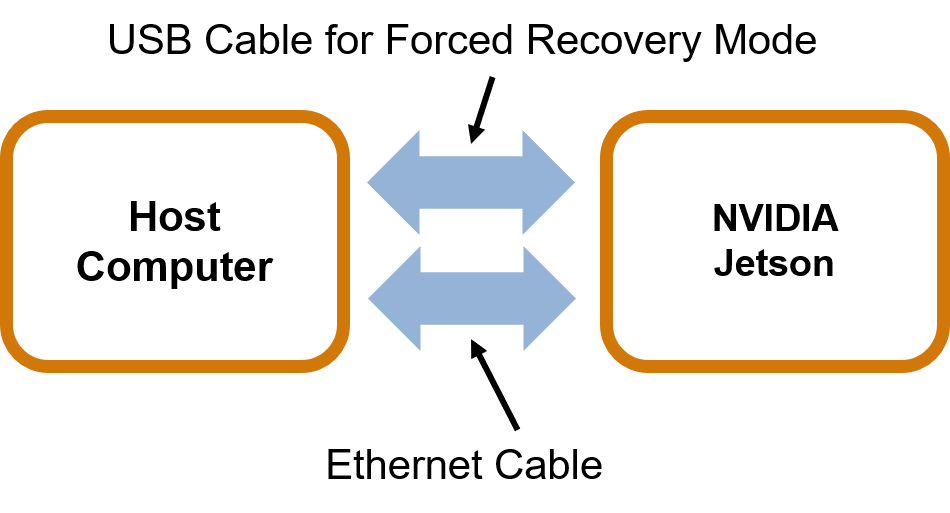

***Fig. 1: Jetson Setup Schematic***

          **補充說明：**

　　　一開始必須先下載檔案燒機，裝在記憶卡中啟動。

　　　[https://developer.nvidia.com/embedded/learn/get-started-jetson-nano-devkit#intro](https://developer.nvidia.com/embedded/learn/get-started-jetson-nano-devkit#intro)

　　　之後兩條路可以走 裝SDK Manager or  JetPack 

           建議可以使用SDK Manager在Jetson Nano中可以裝4.1版本以上的JetPack(建議4.3版)。 

           連接Jetson Nano的方法可以透過同網域的無線網路，或是Usb對接。

　　　**Supplement：**

　　　At the beginning, you must first download the file and burn it, install it on the memory card and start it.

　　　After that, you can install SDK Manager or JetPack in two ways

           It is recommended to use SDK Manager to install JetPack version 4.1 or higher in Jetson Nano (version 4.3 is 　　　　　recommended).

            The way to connect Jetson Nano can be through the wireless network in the same domain, or USB.

- **Install JetPack on the NVIDIA Jetson:** To flash the NVIDIA Jetson with JetPack, which installs the OS, and the required libraries for deep learning including TensorRT, cuDNN, CUDA Toolkit, OpenCV etc, you will need a linux machine or a linux virtual machine on windows as the host machine. If using a virtual machine ensure sufficient memory allocation for the JetPack files. The JetPack installation folder is about 15 GB. Follow the instructions on this page, choose the NVIDIA SDK Manager Option if you are using a Jetson : [https://docs.nvidia.com/jetpack-l4t/2_1/content/developertools/mobile/jetpack/jetpack_l4t/2.0/jetpack_l4t_install.htm](https://docs.nvidia.com/jetpack-l4t/2_1/content/developertools/mobile/jetpack/jetpack_l4t/2.0/jetpack_l4t_install.htm)        

- **Install the Simple DirectMedia Layer  (SDL v1.2) library:** Open a Terminal on the Jetson and run the following commands

`        $ sudo apt-get install libsdl1.2debian`

`        $ sudo apt-get install libsdl1.2-dev`

- **Environment Variables on NVIDIA Jetson:** Ensure the following environment variables are set on the Jetson by adding the following  `export` command at the very beginning of the `$HOME/.bashrc` file for bash profiles. In a terminal use `sudo gedit $HOME/.bashrc `to open the file and add the following lines of code at the beginning.

            ` export PATH=/usr/local/cuda/bin:$PATH`

`       export LD_LIBRARY_PATH=/usr/local/cuda/lib64:$LD_LIBRARY_PATH`

***On the MATLAB Host***

在MATLAB端就是要確保Compiler版本有對並且支援，可以透過windows的MATLAB去對Jetson Nano轉code

安裝與確定Driver與Toolkit的路徑

Once you have installed JetPack on the NVIDIA jetson following the steps in the link above, a few third party libraries need to be installed on the computer running MATLAB. The computer running MATLAB could be Linux-based or Windows-based. For the rest of this example we will use a Windows machine. Install all the packages listed below:

- [C/C++ Compiler](https://www.mathworks.com/support/requirements/supported-compilers.html):** Microsoft Visual Studio 2013, Microsoft Visual Studio 2015, Microsoft Visual Studio 2017** can be used for **Windows **if using CUDA toolkit v10.0, for v10.1, **Microsoft Visual Studio 2019 **must be used **. **For **Linux **use **GCC C/C++ compiler 6.3.x**. 

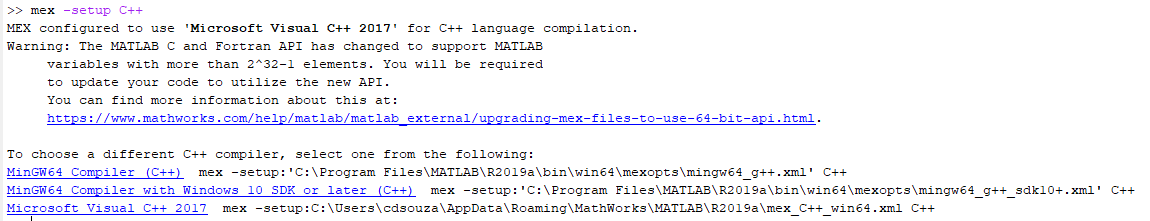

Run the code below to check the compiler setup

mex -setup C++

- [CUDA Toolkit and driver](https://developer.nvidia.com/cuda-toolkit-archive) : GPU Coder has been tested with CUDA toolkit v10.0. The default installation comes with the `nvcc` compiler, `cuFFT`, `cuBLAS`, `cuSOLVER`, and Thrust libraries

- [CUDA Deep Neural Network library (cuDNN)](https://developer.nvidia.com/cudnn): The NVIDIA CUDA® Deep Neural Network library (cuDNN) is a GPU-accelerated library of primitives for deep neural networks. v7 or higher. Download the files and run the installer.

- [NVIDIA TensorRT](https://developer.nvidia.com/tensorrt): High Performance deep learning inference optimizer and runtime library, v6 and later. For R2019b and later GPU Coder supports TensorRT for CUDA Code generation from a Windows Machine.

- [OpenCV Libraries](https://opencv.org/releases/): Open Source Computer Vision Library ([OpenCV](https://opencv.org/)), v3.1.0 is required for deep learning examples. The `OpenCV` library that ships with Computer Vision Toolbox does not have all the required libraries and the [OpenCV](https://opencv.org/) installer does not install them. Therefore, you must download the `OpenCV` source and build the libraries

- CUDA toolkit for ARM® and [Linaro GCC 4.9](https://releases.linaro.org/components/toolchain/binaries/4.9-2016.02/aarch64-linux-gnu/) toolchain for the TX1 and TX2. Use the `gcc-linaro-4.9-2016.02-x86_64_aarch64-linux-gnu` release tarball.

Once all the third-party software libraries have been downloaded and installed, set up the environment variables so MATLAB can locate the necessary libraries, compilers and tools to generate CUDA code. **These environment variables will delete themselves everytime you restart MATLAB. To overcome this, you can add the code below to a startup script, edit as apporipriate for your machine**. Click this link to learn more : [https://www.mathworks.com/help/releases/R2019a/gpucoder/gs/setting-up-the-toolchain.html](https://www.mathworks.com/help/releases/R2019a/gpucoder/gs/setting-up-the-toolchain.html) 

建議直接將環境變數設定在主機上

(It is recommended to set environment variables directly on the host)

setenv('CUDA_PATH',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","v10.0"))
setenv('NVIDIA_CUDNN',fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","cuDNN"));
setenv('NVIDIA_TENSORRT', fullfile("C:","Program Files","NVIDIA GPU Computing Toolkit","CUDA","TensorRT"))
setenv('OPENCV_DIR',fullfile("C:","Program Files","opencv","build"));
setenv('PATH', ... 
    [fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','v10.0','bin') ';' ...
    fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','cuDNN','bin') ';'...
    fullfile('C:','Program Files','opencv','build','x64','vc15','bin') ';'...
    fullfile('C:','Program Files','NVIDIA GPU Computing Toolkit','CUDA','TensorRT','lib') ';'...
    getenv('PATH')]);


## Step 2: Connect to Jetson and Verify Setup

連結Jetson的網域與帳號密碼

Link Jetson's domain and account password

`hwobj= jetson(``'host-name'``,``'username'``,``'password'``);`

hwobj= jetson('192.168.xx.xxx','username','password');

Function definitions in a script must appear at the end of the file.
Move all statements after the "resnet50_wrapper" function definition to before the first local function definition.


envCfg = coder.gpuEnvConfig('jetson');
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodegen = 1;
envCfg.Quiet = 1;
envCfg.HardwareObject = hwobj;
coder.checkGpuInstall(envCfg);

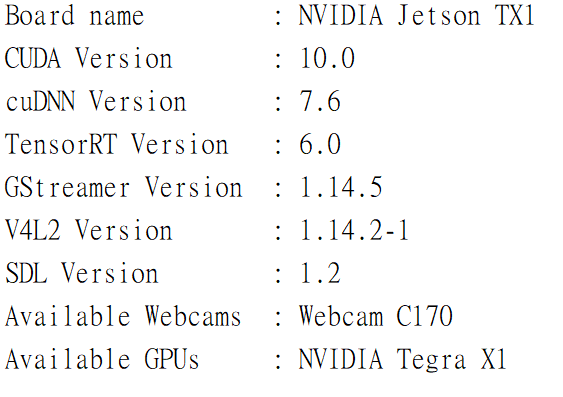

MATLAB Command Window: Enter gpucoderSetup

gpucoderSetup

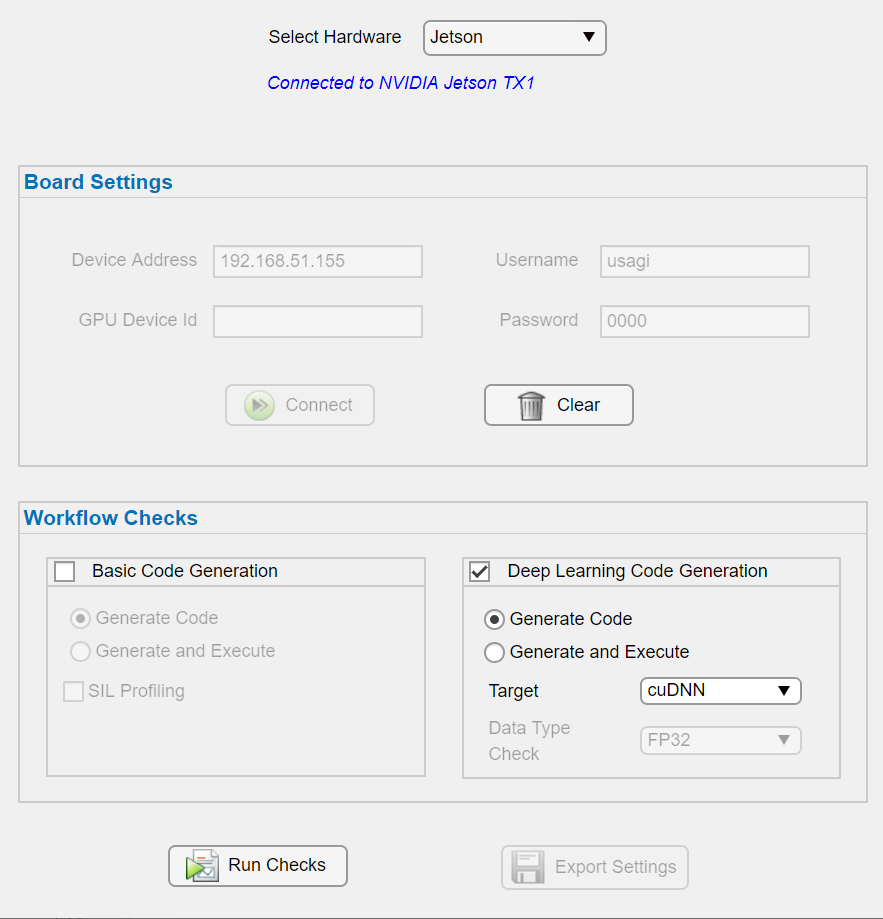

## Step 3: Prepare the MATLAB Code

準備好MATLAB Code並且要做修改

Prepare MATLAB Code and modify it.

type resnet50_wrapper
cfg = coder.gpuConfig('exe');
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');

im=single(imread('peppers.png'));
im=imresize(im,[224,224]);

cfg.CustomSource=fullfile('main_resnet50.h');
cfg.CustomSource=fullfile('main_resnet50.cu');


在 resnet50_wrapper中要做修改，將opencv改成opencv4

To modify in resnet50_wrapper, change opencv to opencv4.

function out = resnet50_wrapper(im) %#codegen

opencv_link_flags = '`pkg-config --cflags --libs opencv4`';
coder.updateBuildInfo('addLinkFlags',opencv_link_flags);

persistent rnet;
if isempty(rnet)
    rnet = resnet50();
end
out = rnet.predict(im);

end

在main_resnet50.cu中要做更改

Make changes in main_resnet50.cu

code 16 line

#define VID_DEV_ID 1   >   #define VID_DEV_ID -1

code 67 69 71 73 75 77 line

cvPoint(30,30), CV_FONT_HERSHEY_DUPLEX   >    Point(30,30), FONT_HERSHEY_DUPLEX

cvPoint and  CV_FONT_HERSHEY_DUPLEX  was written in the old version opencv2.4.9,and I use opencv 4.1.1

code 120 line

CV_WINDOW_NORMAL  >  WINDOW_NORMAL

## Step 4: Setting in Jetson Nano

將opencv4裡面的opencv2搬移到/usr/include/之下

**Rename *****/usr/include/opencv4/opencv2 *****to *****/usr/include/opencv2***

mv /usr/include/opencv4/opencv2 /usr/include/opencv2

## Step 5: Generate Code

codegen -config cfg -args {im} resnet50_wrapper -report
hwobj.putFile('synsetWords_resnet50.txt',hwobj.workspaceDir);
hwobj.runApplication('resnet50_wrapper');

## Step 6: Start Application

在Nano上需要使用sudo來做啟動

Need to use sudo to start on Nano